pose = zeros(2000, 5);

for i=1:900

r1 = (i-1)/10 * pi / 180;
theta = [r1 0 0 0 0];
[x, y, z, ry, rz] = D5R_FwKine(theta(1), theta(2), theta(3), theta(4), theta(5));
pose(i,:) = [x, y, z, ry, rz];

end

pose
plot3(pose(1:900,1), pose(1:900,2), pose(1:900,3))

for i=1:900
    r5 = (i) / 10 * pi /180;
    theta = [pi/2 0 0 0 r5];
    [x, y, z, ry, rz] = D5R_FwKine(theta(1), theta(2), theta(3), theta(4), theta(5));
    pose(900+i,:) = [x, y, z, ry, rz];
end
pose
plot3(pose(1:1800,1), pose(1:1800,2), pose(1:1800,3))

iter = 3601;
toolPose = zeros(iter, 5);

for i=1:iter

r1 = (i-1)/10;
theta = [r1 10 0 0 90];
[x, y, z, ry, rz] = D5RTool_FwKine(theta(1), theta(2), theta(3), theta(4), theta(5));

toolPose(i,:) = [x, y, z, ry, rz];

end

toolPose
% plot3(toolPose(:,1), toolPose(:,2), toolPose(:,3))
plot(toolPose(1:iter, 1), toolPose(1:iter, 2));
xlabel("x");
ylabel("y");
axis equal

iter = 3601;
toolPose = zeros(iter, 5);

for i=1:iter

r5 = (i-1)/10;
theta = [0 0 0 0 r5];
[x, y, z, ry, rz] = D5RTool_FwKine(theta(1), theta(2), theta(3), theta(4), theta(5));

toolPose(i,:) = [x, y, z, ry, rz];

end

toolPose

toolPose =    67.9000  -76.8500 -105.2500         0         0
   67.9483  -76.8500 -105.1314   -0.1000         0
   67.9965  -76.8500 -105.0128   -0.2000         0
   68.0444  -76.8500 -104.8941   -0.3000         0
   68.0921  -76.8500 -104.7753   -0.4000         0
   68.1396  -76.8500 -104.6564   -0.5000         0
   68.1869  -76.8500 -104.5374   -0.6000         0
   68.2340  -76.8500 -104.4184   -0.7000         0
   68.2808  -76.8500 -104.2993   -0.8000         0
   68.3275  -76.8500 -104.1800   -0.9000         0


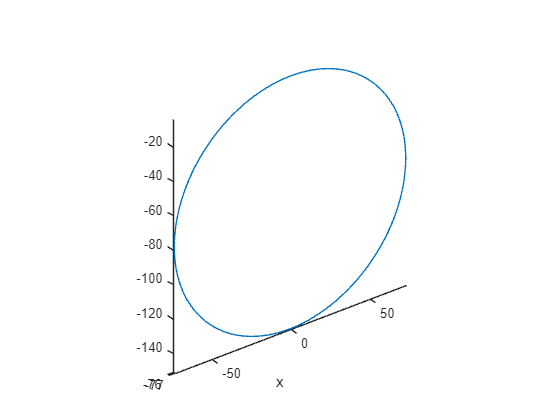

% plot3(toolPose(:,1), toolPose(:,2), toolPose(:,3))
plot3(toolPose(1:iter, 1), toolPose(1:iter, 2), toolPose(1:iter, 3));
xlabel("x");
ylabel("z");
axis equal

[r1, p2, p3, p4, r5] = D5RTool_InvKine(toolPose(:,1), toolPose(:,2), toolPose(:,3), toolPose(:,4),toolPose(:,5))

r1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


p2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


p3 = 1.0e-14 *

         0
   -0.3365
   -0.0139
   -0.6772
   -0.0749
   -0.0250
   -0.2220
   -0.5385
   -0.4718
   -0.0500


p4 = 1.0e-13 *

         0
         0
         0
    0.1421
         0
         0
         0
         0
         0
         0


r5 =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


x =    67.9000
   67.9483
   67.9965
   68.0444
   68.0921
   68.1396
   68.1869
   68.2340
   68.2808
   68.3275


y =   -76.8500
  -76.8500
  -76.8500
  -76.8500
  -76.8500
  -76.8500
  -76.8500
  -76.8500
  -76.8500
  -76.8500


z =  -105.2500
 -105.1314
 -105.0128
 -104.8941
 -104.7753
 -104.6564
 -104.5374
 -104.4184
 -104.2993
 -104.1800


ry =          0
   -0.1000
   -0.2000
   -0.3000
   -0.4000
   -0.5000
   -0.6000
   -0.7000
   -0.8000
   -0.9000


rz =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


iter = 3601;
joints = zeros(iter, 5);

for i=1:iter

rz = (i-1)/10;
pose = [67.9 -76.85 -105.25 0 rz];
[r1, p2, p3, p4, r5] = D5RTool_InvKine(pose(1), pose(2), pose(3), pose(4), pose(5));

joints(i,:) = [r1, p2, p3, p4, r5];

end

joints

joints =          0         0         0         0         0
    0.1000    0.1184   -0.1342         0         0
    0.2000    0.2365   -0.2687         0         0
    0.3000    0.3545   -0.4033         0         0
    0.4000    0.4722   -0.5382         0         0
    0.5000    0.5896   -0.6732         0         0
    0.6000    0.7068   -0.8085         0         0
    0.7000    0.8238   -0.9439         0         0
    0.8000    0.9405   -1.0796         0         0
    0.9000    1.0570   -1.2155         0         0


% plot3(toolPose(:,1), toolPose(:,2), toolPose(:,3))
% plot3(toolPose(1:iter, 1), toolPose(1:iter, 2), toolPose(1:iter, 3));
% xlabel("x");
% ylabel("z");
% axis equal

[x, y, z, ry, rz] = D5RTool_FwKine(joints(80,1), joints(80,2), joints(80,3), joints(80,4), joints(80,5))

x = 67.9000

y = -76.8500

z = -105.2500

ry = 0

rz = 7.9000